clear all
clc
close all

load('dataForLearning.mat') 
graph.drawGraph(1);
graph.loadNeighbors();

## Drawing box plots

#### Generating data for box plots

% Agent,
agentId = 1;
% RHCP
RHCPId = 2;
numOfTargets = length(graph.targets);

collectedDataMatrix = cell(numOfTargets,numOfTargets);
dataCountMatrix = zeros(numOfTargets,numOfTargets);
for dataBlock = graph.agents(agentId).pastData
    dataBlock = cell2mat(dataBlock);
    if (RHCPId==2 & size(dataBlock,2)==3) | (RHCPId==1 & size(dataBlock,2)==4)
        i = dataBlock(1,1);
        jStar = dataBlock(1,size(dataBlock,2));
        if isempty(collectedDataMatrix{i,jStar})
            collectedData = cell(1,numOfTargets);
        else
            collectedData = collectedDataMatrix{i,jStar};
        end
        
        for jId = 1:1:size(dataBlock,1)
            j = dataBlock(jId,1);
            Omega_j = dataBlock(jId,2);
            collectedData{j} = [collectedData{j}, Omega_j];    
        end
        collectedDataMatrix{i,jStar} = collectedData;
        dataCountMatrix(i,jStar) = dataCountMatrix(i,jStar) + 1; 
    end
end
dataCountMatrix

#### Drawing

for i = 1:1:numOfTargets
    figs = [];
    maxOmega_j = 0;
    for jStar = 1:1:numOfTargets
        if dataCountMatrix(i,jStar)>0 & i~=jStar
            collectedData = collectedDataMatrix{i,jStar};
            data = [];
            dataCenters = [];
            for j = 1:1:numOfTargets
                L = length(collectedData{j}); 
                if L > 0
                    data = [data; transpose(collectedData{j})];
                    newLabels = repmat({['j=',num2str(j)]}, L, 1);
                    dataCenters = [dataCenters; newLabels];  
                end
            end
            figure
            boxplot(data,dataCenters)
            title(['Agent ',num2str(agentId),' at target ',num2str(i),' selecting $j^*=',...
                num2str(jStar),'$ (No. of observations: ',num2str(dataCountMatrix(i,jStar)),').'],"Interpreter","latex");
            xlabel('Next Visit: $j$',"Interpreter","latex");
            ylabel('Target State: $\Omega_j$',"Interpreter","latex");
            
            fig = gcf;
            figs = [figs, fig.Number];
            maxData = max(data);
            if maxData > maxOmega_j
                maxOmega_j = maxData;
            end
            
        end  
    end
    
    for fig = figs
        figure(fig);
        ylim([0,maxOmega_j]);
    end
    
end

### Generating input output data for Neural Networks

agentId = 1;
RHCPId = 1;
numOfTargets = length(graph.targets); 

collectedInputMatrix = cell(1,numOfTargets);
collectedOutputMatrix = cell(1,numOfTargets);
dataCountMatrix = zeros(numOfTargets,numOfTargets);

for dataBlock = graph.agents(agentId).pastData
    dataBlock = cell2mat(dataBlock);
    if (RHCPId==2 & size(dataBlock,2)==3) | (RHCPId==1 & size(dataBlock,2)==4)
        i = dataBlock(1,1); % current target
        jStar = dataBlock(1,size(dataBlock,2));
        if i == jStar
            continue;
        end
        
        % output
        
        neighborIndex = find(graph.neighbors{i}==jStar)-1;
        output = zeros(length(graph.neighbors{i})-1,1);
        output(neighborIndex) = 1;
        collectedOutputMatrix{i} = [collectedOutputMatrix{i}, output];
        
        % input
        input = zeros(length(graph.neighbors{i}),1);
        for jId = 1:1:size(dataBlock,1)
            j = dataBlock(jId,1);
            neighborIndex = find(graph.neighbors{i}==j);
            
            Omega_j = dataBlock(jId,2);
            input(neighborIndex) = Omega_j;
        end
        collectedInputMatrix{i} = [collectedInputMatrix{i}, input];
        
        dataCountMatrix(i,jStar) = dataCountMatrix(i,jStar) + 1; 
    end
end
dataCountMatrix

Learning for each target (As a whole)

for i = 1:1:numOfTargets
    inputs = collectedInputMatrix{i};
    targets = collectedOutputMatrix{i};
    
    hiddenLayerSize = [10,10];
    net = patternnet(hiddenLayerSize);
    
    net.divideParam.trainRatio = 70/100;
    net.divideParam.valRatio = 15/100;
    net.divideParam.testRatio = 15/100;
    
    [net,tr] = train(net,inputs,targets);

    outputs = net(inputs);
%     errors = gsubtract(targets,outputs)
    i
    cases = sum(dataCountMatrix(i,:))
    performance = perform(net,targets,outputs)
    
%     figure, plotperform(tr);
%     figure, plottrainstate(tr);
    figure, plotconfusion(targets,outputs);
%     figure, ploterrhist(errors)
    
end

### Learning (online)

close all
rand('seed', 7);

agentId = 1;
collectedInputMatrix = cell(numOfTargets,2);
collectedOutputMatrix = cell(numOfTargets,2);
dataCountMatrix = zeros(numOfTargets,2);
slidingWindowWidth = 15;

hiddenLayerSize = [10]; % onelayer with 10 neurons
net = patternnet(hiddenLayerSize);
nets = cell(numOfTargets,2);
[nets{:}] = deal(net); % repmat version

errors = cell(numOfTargets,2);


for dataBlock = graph.agents(agentId).pastData
    dataBlock = cell2mat(dataBlock);
    
    i = dataBlock(1,1); % current target
    jStar = dataBlock(1,size(dataBlock,2));
    if i == jStar
        continue;
    end
    RHCPId = 1*(size(dataBlock,2)==4) + 2*(size(dataBlock,2)==3);%1 or 2
    dataCountMatrix(i,RHCPId) = dataCountMatrix(i,RHCPId) + 1; 
    
    % output
    neighborIndex = find(graph.neighbors{i}==jStar)-1;
    output = zeros(length(graph.neighbors{i})-1,1);
    output(neighborIndex) = 1;
    collectedOutputMatrix{i,RHCPId} = [collectedOutputMatrix{i,RHCPId}, output];
        
    
    % input
    input = zeros(length(graph.neighbors{i}),1);
    for jId = 1:1:size(dataBlock,1)
        j = dataBlock(jId,1);
        neighborIndex = find(graph.neighbors{i}==j);
        
        Omega_j = dataBlock(jId,2);
        input(neighborIndex) = Omega_j;
    end
    collectedInputMatrix{i,RHCPId} = [collectedInputMatrix{i,RHCPId}, input];
        
    
    % learn
    if dataCountMatrix(i,RHCPId) > slidingWindowWidth
        net = nets{i,RHCPId};
        inputWindow =  collectedInputMatrix{i,RHCPId}(:,end-slidingWindowWidth+1:end);
        outputWindow =  collectedOutputMatrix{i,RHCPId}(:,end-slidingWindowWidth+1:end);
        
        [flag,~,~] = isconfigured(net);
        if ~flag
            disp(['Target ',num2str(i),' RHCP ',num2str(RHCPId),' learning began']);
            net = configure(net,inputWindow,outputWindow);
            net.trainParam.showWindow = 0;
            net = train(net,inputWindow,outputWindow);
        end
        
        result = net(input);
        e = perform(net,output,result);
        
        if 1-max(result)>0.05 %e > 0.1
            disp(['Target ',num2str(i),' RHCP ',num2str(RHCPId),' Re-learned']);
            net = train(net,inputWindow,outputWindow);
            
            result = net(input);
            e = perform(net,output,result);
        end
        
        errors{i,RHCPId} = [errors{i,RHCPId}, e];
        nets{i,RHCPId} = net;
    end
    
end


sum = 0;
for i = 1:1:numOfTargets
    for RHCPId = 1:2
        
        e = errors{i,RHCPId};
        
        
        inputs = collectedInputMatrix{i,RHCPId};
        outputs = collectedOutputMatrix{i,RHCPId};
        net = nets{i,RHCPId};
        
        [configed,~,~] = isconfigured(net);
        if configed
            results = net(inputs);
        
            performance = perform(net,outputs,results)
            sum = sum+performance;
            figure, plotconfusion(outputs,results);
            
            figure
            plot(e)
            xlabel('Instance')
            ylabel('Error')
            title(['Target ',num2str(i),', RHCP ', num2str(RHCPId)])
            
        end
    end
    
end
sum

### Execution time plots

% clear all
close all
% clc

load Case1L_4.mat

t = [];
et = [];
for agentId = 1:1:2
    t = [t; agents(agentId).executionTimes(:,1)];
    et = [et; agents(agentId).executionTimes(:,3)];
end

figure(1)
plot(t,et,'.')

windowSize = 10; % seconds
stepSize = 0.01;
smoothArray = [];
% countArray = [];
for tVal = 0:stepSize:(t(end)-windowSize)
    window = et(t>tVal & t<tVal+windowSize);
    smoothArray = [smoothArray; tVal,mean(window)];
%     countArray = [countArray; length(window)];
end

figure(2)
plot(smoothArray(:,1),smoothArray(:,2))



load Case1_4.mat

t = [];
et = [];
for agentId = 1:1:2
    t = [t; agents(agentId).executionTimes(:,1)];
    et = [et; agents(agentId).executionTimes(:,3)];
end

figure(1)
hold on
plot(t,et,'r.')
grid on
legend('With Learning','Without Learning','Location','NW')
xlabel('Time')
ylabel('Execution time for a RHCP')


smoothArray = [];
for tVal = 0:stepSize:(t(end)-windowSize)
    window = et(t>tVal & t<tVal+windowSize);
    smoothArray = [smoothArray; tVal,mean(window)];
end

figure(2)
hold on
plot(smoothArray(:,1),smoothArray(:,2),'r')
legend('With Learning','Without Learning','Location','NW')
grid on
xlabel('Time')
ylabel('Average execution time for a RHCP')




% Matlab solver:
load Case1_2.mat

t = [];
et = [];
for agentId = 1:1:2
    t = [t; agents(agentId).executionTimes(:,1)];
    et = [et; agents(agentId).executionTimes(:,3)];
end

figure(1)
hold on
plot(t,et,'k.')
grid on
legend('GD with Learning','Gradient Descent (GD)','Matlab Solver','Location','NW')
xlabel('Time')
ylabel('Execution time for a RHCP')


smoothArray = [];
for tVal = 0:stepSize:(t(end)-windowSize)
    window = et(t>tVal & t<tVal+windowSize);
    smoothArray = [smoothArray; tVal,mean(window)];
end

figure(2)
hold on
plot(smoothArray(:,1),smoothArray(:,2),'k')
legend('GD with Learning','Gradient Descent (GD)','Matlab Solver','Location','NW')
grid on
xlabel('Time')
ylabel('Average execution time for a RHCP')


J plots

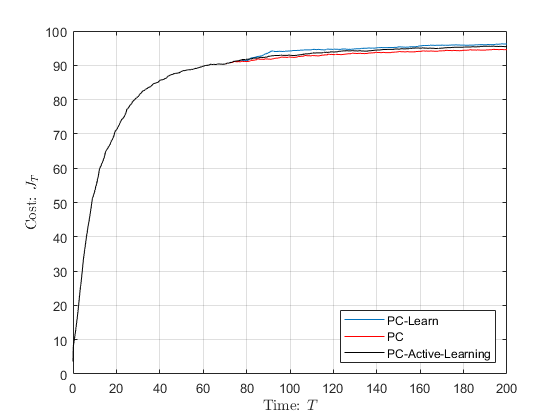

% load Case2L_2.mat
load('Results\ET\Case1L_4.mat')

timeResolution = 0.001;
periodT = 200;
numOfTargets = size(data,2);

timeSeries = 0:timeResolution:periodT;
sumOmega = zeros(periodT/timeResolution+1,1);
for i = 1:1:numOfTargets
    sumOmega = sumOmega + data(:,i,3);
end
    
sumOmega_old = 0;
sumVal = 0;
intSumOmega = zeros(periodT/timeResolution+1,1);
count = 1;
factor = 0.5*timeResolution;
timePeriod = 0;
for sumOmega_k = sumOmega'
    timePeriod = timePeriod + timeResolution;
    sumVal = sumVal + factor*(sumOmega_k + sumOmega_old);
    intSumOmega(count) = sumVal/timePeriod;
    count = count + 1;
    sumOmega_old = sumOmega_k; 
end
figure(3)
plot(timeSeries, intSumOmega)


% load Case2_2.mat
load('Results\ET\Case1_4.mat')

sumOmega = zeros(periodT/timeResolution+1,1);
for i = 1:1:numOfTargets
    sumOmega = sumOmega + data(:,i,3);
end
    
sumOmega_old = 0;
sumVal = 0;
intSumOmega = zeros(periodT/timeResolution+1,1);
count = 1;
factor = 0.5*timeResolution;
timePeriod = 0;
for sumOmega_k = sumOmega'
    timePeriod = timePeriod + timeResolution;
    sumVal = sumVal + factor*(sumOmega_k + sumOmega_old);
    intSumOmega(count) = sumVal/timePeriod;
    count = count + 1;
    sumOmega_old = sumOmega_k; 
end
figure(3)
hold on
plot(timeSeries, intSumOmega,'r')
ylabel('Cost: $J_T$','Interpreter','Latex')
xlabel('Time: $T$','Interpreter','Latex')
legend('With Learning','Without Learning','Location','SE')
grid on



% load Case1_2.mat
load('Results\ET\Case1RL_10.mat')

sumOmega = zeros(periodT/timeResolution+1,1);
for i = 1:1:numOfTargets
    sumOmega = sumOmega + data(:,i,3);
end
    
sumOmega_old = 0;
sumVal = 0;
intSumOmega = zeros(periodT/timeResolution+1,1);
count = 1;
factor = 0.5*timeResolution;
timePeriod = 0;
for sumOmega_k = sumOmega'
    timePeriod = timePeriod + timeResolution;
    sumVal = sumVal + factor*(sumOmega_k + sumOmega_old);
    intSumOmega(count) = sumVal/timePeriod;
    count = count + 1;
    sumOmega_old = sumOmega_k; 
end
figure(3)
hold on
plot(timeSeries, intSumOmega,'k')
% legend('GD with Learning','Gradient Descent (GD)','Matlab Solver','Location','SE')
legend('PC-Learn','PC','PC-Active-Learning','Location','SE')
grid on

tArray = [];
for i = 1:1:10000
    tic;
        syms x;
        a = rand(1,1);
        b = rand(1,1);
        c = rand(1,1);
        S = vpasolve(a*x^4 + b*x^3 - c*x^2 - a*x + b == c, x);
    tVal = toc;
    tArray = [tArray; tVal];
    
    if rem(i,1000)==0
        i
    end
end
figure
plot(tArray);

### Neural Network Demo

clc
clear all
close all

% Solve a Pattern Recognition Problem with a Neural Network
% Script generated by NPRTOOL
%
% This script assumes these variables are defined:
%
%   cancerInputs - input data.
%   cancerTargets - target data.

% No of rows  = dimension of the inputs (Num of features?)
% No of cols  = num of inputs (data points)
inputs  = [0 0 0 0 5 5 5 5; 0 0 5 5 0 0 5 5];

% No of rows = num of outputs we have
% No of cols  = num of inputs (data points)
targets = [1 0 0 0 0 0 0 0; 0 1 1 1 1 1 1 0; 0 0 0 0 0 0 0 1];

% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize);

% Set up Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;


% Train the Network
[net,tr] = train(net,inputs,targets);

% Test the Network
outputs = net(inputs);
errors = gsubtract(targets,outputs);
performance = perform(net,targets,outputs)

% View the Network
view(net)

% Plots
% Uncomment these lines to enable various plots.
figure, plotperform(tr)
figure, plottrainstate(tr)
figure, plotconfusion(targets,outputs)
figure, ploterrhist(errors)